**Part D (a,b)**

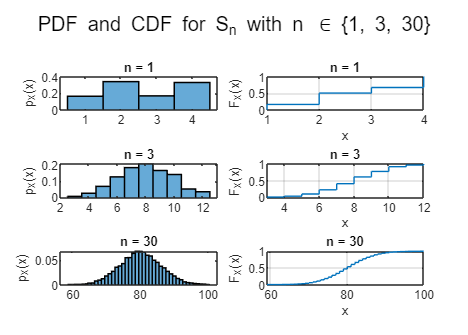

close all;clear all;

X=zeros(30,10000);
for i=1:30
    X(i,:) = randsample(4, 10000, true, [1/6 2/6 1/6 2/6]);
end

Sn = cumsum(X); 


Gaussian_n_1 = makedist('Normal',  mu=1 * (8/3), sigma=sqrt(11/9));
Gaussian_n_3 = makedist('Normal',  mu=3 * (8/3), sigma=sqrt(3 * 11/9));
Gaussian_n_30 = makedist('Normal', mu=30 * (8/3), sigma=(sqrt(30 * 11/9)));

figure
s(1) = subplot(3,2,1) ;
    histogram(Sn(1,:),'Normalization','pdf',LineWidth=1);
    title(s(1),'n = 1')
    ylabel("p_X(x)")
s(2) = subplot(3,2,2) ;
    cdfplot(Sn(1,:))
    title(s(2),'n = 1')
    ylabel("F_X(x)")
s(3) = subplot(3,2,3);
    histogram(Sn(3,:),'Normalization','pdf',LineWidth=1)
    title(s(3),'n = 3')
    ylabel("p_X(x)")
s(4) = subplot(3,2,4);
    cdfplot(Sn(3,:))
    title(s(4),'n = 3')
    ylabel("F_X(x)")
s(5) = subplot(3,2,5);
    histogram(Sn(30,:),'Normalization','pdf',LineWidth=1)
    title(s(5),'n = 30')
    ylabel("p_X(x)")
s(6) = subplot(3,2,6);
    cdfplot(Sn(30,:))
    title(s(6),'n = 30')
    ylabel("F_X(x)")
sgtitle({'PDF and CDF for S_n with n \in \{1, 3, 30\}'})

**Part D (c)**

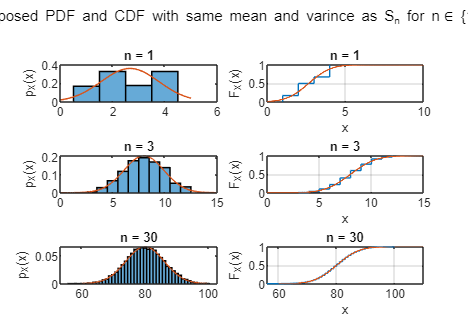

close all;
figure
s(1) = subplot(3,2,1) ;
    histogram(Sn(1,:),'Normalization','pdf',LineWidth=1);
    hold on;
    x = 0:0.01:5;
    plot(x,Gaussian_n_1.pdf(x));
    hold off;
    title(s(1),'n = 1')
    ylabel("p_X(x)")
s(2) = subplot(3,2,2) ;
    cdfplot(Sn(1,:))
    hold on;
    x = 0:0.01:10;
    plot(x,Gaussian_n_1.cdf(x),LineWidth=1);
    hold off;
    title(s(2),'n = 1')
    ylabel("F_X(x)")
s(3) = subplot(3,2,3);
    histogram(Sn(3,:),'Normalization','pdf',LineWidth=1)
    hold on;
    x = 0:0.01:15;
    plot(x,Gaussian_n_3.pdf(x));
    hold off;
    title(s(3),'n = 3')
    ylabel("p_X(x)")
s(4) = subplot(3,2,4);
    cdfplot(Sn(3,:))
    hold on;
    x = 0:0.01:15;
    plot(x,Gaussian_n_3.cdf(x),LineWidth=1);
    hold off;
    title(s(4),'n = 3')
    ylabel("F_X(x)")
s(5) = subplot(3,2,5);
    histogram(Sn(30,:),'Normalization','pdf',LineWidth=1)
    hold on;
    x = 60:0.01:100;
    plot(x,Gaussian_n_30.pdf(x));
    hold off;
    title(s(5),'n = 30')
    ylabel("p_X(x)")
s(6) = subplot(3,2,6);
    cdfplot(Sn(30,:))
    hold on;
    x = 60:0.01:110;
    plot(x,Gaussian_n_30.cdf(x),LineWidth=1);
    hold off;
    title(s(6),'n = 30')
    ylabel("F_X(x)")
sgtitle({'Superimposed PDF and CDF with same mean and varince as S_n for n\in \{1, 3, 30\}'},"Fontsize",10)

%Again, we observed that when n is increased, Sn looks more like a gaussian
%distribution as we expect from CLT.